clc;
clear all;
close all;

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=25 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


This code evaluates the peak time

$t_\text{peak}=\frac{L}{v_\text{char}}-\frac{2D_\text{eff}}{v^2_\text{char}}$ (1)

where $D_\text{eff}$ is the effective diffusion coefficient given by [1, Eq. (4.54) pp. 77]

$D_\text{eff}=D_\text{coeff}\left(1+\frac{1}{200}\text{Pe}^2\right)$,  (2)

$v_\text{char}$ is the characteristic speed, here evalueated as the average speed within the microfluidic pipe as [1, below Eq. (3.40) pag. 53]

$v_\text{char}=\frac{Q}{w\times \text{height pipe}}$, (3)

and $\text{Pe}$ is the Peclet number evaluated as [3, Eq. below 11]

$\text{Pe}=\frac{v_\text{char}\times \text{height pipe}}{D_\text{coeff}}$ (4)

Q_uL_min=1;
Q=Q_uL_min/6e10;

w_1=w_Pipe_min;

disp(['Q_inlet_CNN=',num2str(Q_inlet_CNN*6e10),' uL/min'])

Q_inlet_CNN=5 uL/min


#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

for i_w=1:length(w_vec)
    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        % R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        % Q=p0/R;
        

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        % D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
            %recording the lenght of the pipe
            if(i_w==1)
                l_vec_max_idx=i_l;
            end
            if(i_w==length(w_vec))
                l_vec_min_idx=i_l;
            end
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end


## Plotting the Pe_cond matrix

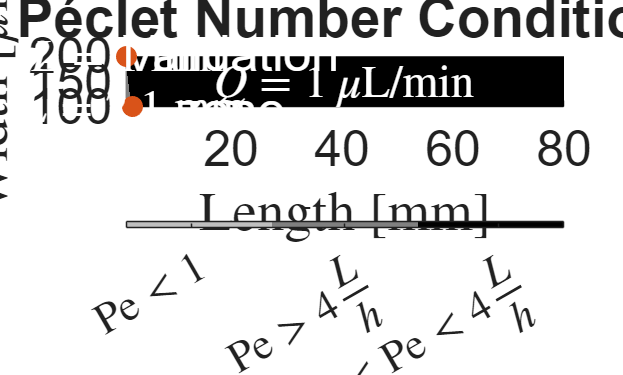

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(end/2)*1e3,w_vec(end/2)*1e6,{strcat('$Q=',num2str(Q*6e10,2),'\, \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

%lenght and width annotations
plot(l_vec(l_vec_max_idx)*1e3, w_vec(1)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(l_vec_min_idx)*1e3, w_vec(end)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
text(l_vec(l_vec_max_idx)*1e3,w_vec(1)*1e6,{strcat('$L=',num2str(l_vec(l_vec_max_idx)*1e3,2),' $ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(l_vec_min_idx)*1e3,w_vec(end)*1e6,{strcat('$L=',num2str(l_vec(l_vec_min_idx)*1e3,2),'$ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

Peclet condition for a fixed pipe width versus Q and pipe Volume

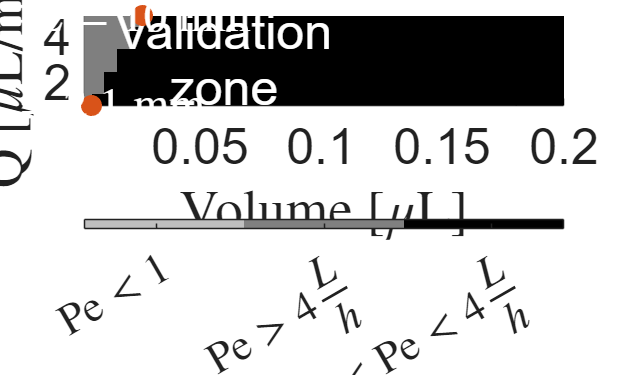

%width of the pipes
w_pipe=w_vec(1);

Q_uL_minute_vec=[1 2 3 4 5];
Q_vec=Q_uL_minute_vec/6e10;

Pe_cond=zeros(length(Q_vec),length(l_vec));

l_vec_min_idx_vs_Q=zeros(1,length(Q_vec));

for i_Q=1:length(Q_vec)
    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        % R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        % Q=p0/R;
        

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q_vec(i_Q)/(w_pipe*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        % D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_Q,i_l)=1;

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_Q,i_l)=0;
            %recording the lenght of the pipe
            if(i_Q==1)
                l_vec_max_idx=i_l;
            end
            if(i_Q==length(Q_vec))
                l_vec_min_idx=i_l;
            end

            l_vec_min_idx_vs_Q(i_Q)=i_l;
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_Q,i_l)=-1;
        end
    end
end

figure;
% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*w_vec(1)*height_pipe*1e9, Q_uL_minute_vec, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(0.06,3,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

%text(l_vec(end/2)*1e3,Q_uL_minute_vec(end/2)*1e6,{strcat('$Q=',num2str(Q*6e10,2),'\, \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

%lenght and width annotations
plot(l_vec(l_vec_max_idx)*w_vec(1)*height_pipe*1e9, Q_uL_minute_vec(1),'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(l_vec_min_idx)*w_vec(1)*height_pipe*1e9, Q_uL_minute_vec(end),'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
text(l_vec(l_vec_max_idx)*w_vec(1)*height_pipe*1e9,Q_uL_minute_vec(1),{strcat('$L=',num2str(l_vec(l_vec_max_idx)*1e3,2),' $ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(l_vec_min_idx)*w_vec(1)*height_pipe*1e9,Q_uL_minute_vec(end),{strcat('$L=',num2str(l_vec(l_vec_min_idx)*1e3,2),'$ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Volume [$\mu$L]','Interpreter','latex');
ylabel('Q [$\mu$L/min]','Interpreter','latex');
axis([l_vec(1)*w_vec(1)*height_pipe*1e9 l_vec(end)*w_vec(1)*height_pipe*1e9 Q_uL_minute_vec(1) Q_uL_minute_vec(end)])
set(gca, 'YDir', 'normal');
%title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

#### Peak time

Description: Evaluating the peak time of received pulses for a fixed width vs Q and V.

disp(['w_Pipe_min=',num2str(w_pipe*1e6),' um'])

w_Pipe_min=100 um



w_pipe=w_vec(1);
disp(['w_Pipe_min=',num2str(w_pipe*1e3),' mm'])

w_Pipe_min=0.1 mm


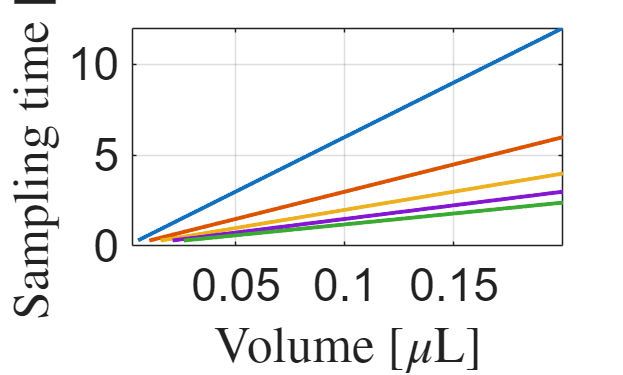


t_pred=zeros(length(Q_vec),length(l_vec));

for i_Q=1:length(Q_vec)
    %Mean velocity
    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_vec(i_Q)/(w_pipe*height_pipe);

    %Peclet number, see [3, Eq. below 11]
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    t_pred(i_Q,:) = l_vec./v_char - 2*D_eff./(v_char.^2);
end

figure;
for k=1:length(Q_vec)
    plot(l_vec(l_vec_min_idx_vs_Q(k):end)*w_pipe*height_pipe*1e9,t_pred(k,l_vec_min_idx_vs_Q(k):end),'LineWidth',2); grid on; hold on;
end
xlabel('Volume [$\mu$L]','Interpreter','latex');
ylabel('Sampling time [s]','Interpreter','latex');
axis([l_vec(1)*w_vec(1)*height_pipe*1e9 l_vec(end)*w_vec(1)*height_pipe*1e9 0 max(max(t_pred))])
set(gca,'FontSize',fontsize-2 ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

#### Pulse response

**Description:** Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition $\mathrm{Pe}<$, the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$, where $x'$ refers to the moving coordinates. The moving coordinates is along the $x$ axis of the unmoved coordinates and moves at the average speed of the velocity profile. Considering the initial conditions [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$, (7)

the solution to the diffusion equation yields [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (8)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \text{erfc}\left(\frac{x-v_\text{char}t}{2\sqrt{D_\text{eff}\,t}}\right)$,          (9)

where [1, Eq. (4.54) pp. 77]

$D_\text{eff}=D_\text{coeff}\left(1+\frac{1}{200}\text{Pe}^2\right)$,        (10)

is the effective diffusion coefficient, and $v_\text{char}$ is the characteristic speed, here evalueated as the average speed within the microfluidic pipe as [1, below Eq. (3.40) pag. 53]

$v_\text{char}=\frac{Q}{w_1\times \text{height pipe}}$, (11)

and $\text{Pe}$ is the Peclet number evaluated as [3, Eq. below 11]

$\text{Pe}=\frac{v_\text{char}\times \text{height pipe}}{D_\text{coeff}}$ (12)

#### Impulse response

**Description:** This block evaluates the channel impulse response $h(t)$ for the turning channel. The $h(t)$ sequence is evaluated using the above formulation for the observed concentration of molecules. The above formulation is the step response of the channel when $C_0=1$, as such, the channel impulse response can be evaluated as [4, Eq. (7b), pp. 78]

$h(t)=\frac{\partial}{\partial t}C(x,t)\bigg|_{C_0=1}$,  (13)

where $C(x,t)$ is given as in Eq. (11) above.

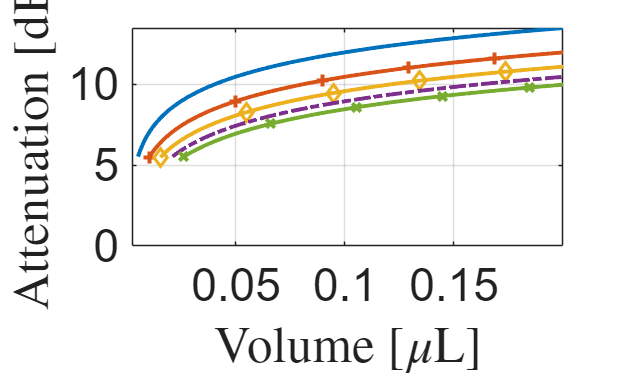

t=0:time_delta/50:20;

Att_dB=zeros(length(Q),length(i_l));

for i_Q=1:length(Q_vec)
    for i_l=1:length(l_vec)
        %Mean velocity
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q_vec(i_Q)/(w_pipe*height_pipe);
    
        %Peclet number, see [3, Eq. below 11]
        Pe=v_char*height_pipe/D_coeff;
    
        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);
    
        %Pulse response
        c_Pipe_1=c_Tartrazine./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
        %Impulse response
        h_Pipe_1=diff(c_Pipe_1)/time_sampling;
        %Gain on the channel
        Att_dB(i_Q,i_l)=-10*log10(trapz(t(1:end-1),h_Pipe_1.^2));
    end
end

color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html

figure;
for k=1:length(Q_vec)
    plot(l_vec(l_vec_min_idx_vs_Q(k):end)*w_pipe*height_pipe*1e9,Att_dB(k,l_vec_min_idx_vs_Q(k):end),...
        marker{k},'LineWidth',2,'Color',color{k},'MarkerIndices',1:100:length(Att_dB)); hold on;
    % plot(l_vec(l_vec_min_idx_vs_Q(k))*w_pipe*height_pipe*1e9,Att_dB(k,l_vec_min_idx_vs_Q(k)),'o','Color','black');
end
grid on;

xlabel('Volume [$\mu$L]','Interpreter','latex');
ylabel('Attenuation [dB]','Interpreter','latex');
axis([l_vec(1)*w_vec(1)*height_pipe*1e9 l_vec(end)*w_vec(1)*height_pipe*1e9 0 max(max(Att_dB))]);
set(gca,'FontSize',fontsize-2 ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

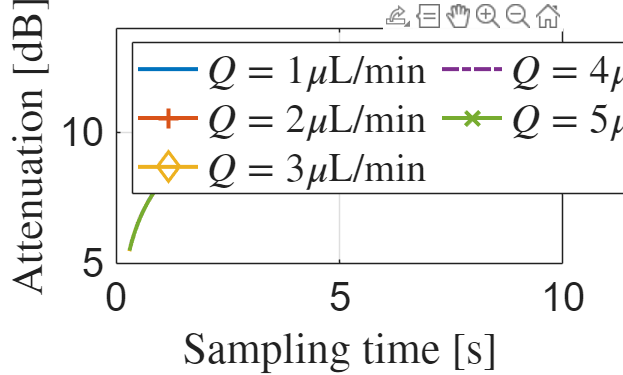


figure;
marker_indices=100+(1:100/length(Q_vec):100);%specify the length between markers in samples (integer values)
for k=1:length(Q_vec)
    plot(t_pred(k,l_vec_min_idx_vs_Q(k):end),Att_dB(k,l_vec_min_idx_vs_Q(k):end),...
        marker{k},'LineWidth',2,'Color',color{k},...
        'MarkerIndices',marker_indices(k):marker_indices(k):length(Att_dB),...
        'MarkerSize',10); grid on; hold on;
end
ylabel('Attenuation [dB]','Interpreter','latex');
xlabel('Sampling time [s]','Interpreter','latex');

legend_text=cell(1,length(Q_vec));
for m=1:length(Q_vec)
  legend_text{m}=strcat('$Q=',num2str(Q_vec(m)*6e10),' \mu$L/min');
end
 
legend({legend_text{:}},...
    'Location','northwest','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize-5);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
 

axis([0 10 5 14])
set(gca,'FontSize',fontsize-5 ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

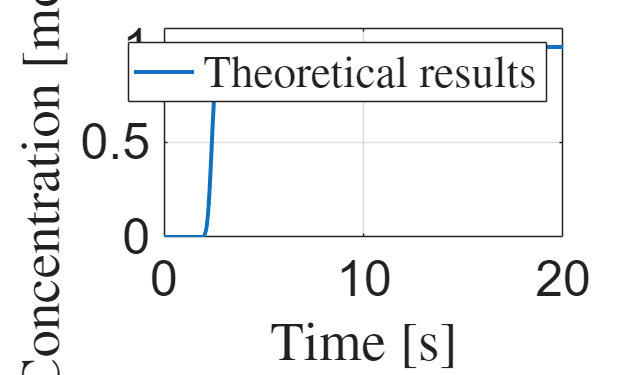


figure;
plot(t,c_Pipe_1,'LineWidth',2); grid on; hold on;
%plot(t_COMSOL,c_COMSOL_Pipe_1,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(c_Pipe_1)]);
legend({'Theoretical results','Simulation in COMSOL'},"Interpreter","latex")


figure;
plot(t(1:end-1),h_Pipe_1,'LineWidth',2); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({'Theoretical results','Simulation in COMSOL'},"Interpreter","latex");

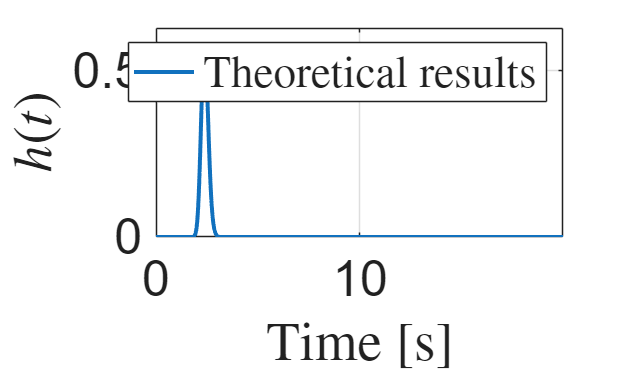

axis([0 t(end-1) 0 1.1*max(h_Pipe_1)]);

### References

[1] H. Bruus, Theoretical Microfluidics. 2008. doi: 10.1093/oso/9780199235087.001.0001.  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, "Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section," Mathematical and Computer Modelling, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: 10.1016/j.mcm.2006.11.029. 

[4] Murat paper